# Scheduled task `🕒`

This is a community version of scheduled task, a service from MathWorks aiming at scheduling data analysis, simulation and AI model training.

**Resources:**

- [Continuous Integration with MATLAB® and GitHub® Actions Workshop](https://github.com/mathworks/ci-with-matlab-and-github-actions-workshop)

- [How to Run MATLAB in GitHub Actions - Youtube](https://www.youtube.com/watch?v=Ndp5kBhOXq4) 

- [Using MATLAB with GitHub Actions - Youtube](https://www.youtube.com/watch?v=Qj5upV0Qm1o) 

- [Learn GitHub Actions](https://docs.github.com/en/actions/learn-github-actions) 

## Architecture

In your repository, create the `.github/workflows/` directory to store your workflow files.

mkdir .github/workflows/
mkdir Tasks
mkdir Data

## Create your first task

The basic example will be checking [Bitcoin prices daily](https://docs.cloud.coinbase.com/sign-in-with-coinbase/docs/api-prices), and storing it into a new row of an existing csv file.

**First iteration** of the task executed locally and interactively:

jason = webread("https://api.coinbase.com/v2/prices/BTC-USD/spot")

jason = struct with fields:
    data: [1x1 struct]


T = struct2table(jason.data)

T = 1x3 table
     amount     base    currency
    ________    ____    ________

    63300.09    BTC       USD   


T.time = datetime("now")

T = 1x4 table
     amount     base    currency            time        
    ________    ____    ________    ____________________

    63300.09    BTC       USD       26-Apr-2024 12:08:59


writetable(T,'Data/btc.csv')

**Second iteration**: Simply read the existing dataset as a timetable and [add a row](https://www.mathworks.com/help/matlab/matlab_prog/add-and-delete-table-rows.html)

% Read input data
T = readtable("Data/btc.csv");
jason = webread("https://api.coinbase.com/v2/prices/BTC-USD/spot");
Tnew = struct2table(jason.data);
Tnew.time = datetime("now");
%  Transform data to fit the input format
Tnew.amount = double(string(Tnew.amount));
Tnew.base = cellstr(Tnew.base);
Tnew.currency = cellstr(Tnew.currency);
T = [T;Tnew] % adding a row

T = 2x4 table
    amount     base      currency            time        
    ______    _______    ________    ____________________

    63300     {'BTC'}    {'USD'}     26-Apr-2024 12:08:59
    63404     {'BTC'}    {'USD'}     26-Apr-2024 12:09:48


% Write output data
writetable(T,'Data/btc.csv')

Save this calculation into a script to run daily: 

edit Tasks/task1.m

## Schedule your task execution

In the `.github/workflows/` directory, create a new file called `task.yml` and add the following code.

edit .github/workflows/task.yml

This will run the [task1.m](matlab:open('./Tasks/task1.m')) on a specific [schedule](https://docs.github.com/en/actions/using-workflows/events-that-trigger-workflows#schedule), here [every 5 minutes](https://crontab.guru/every-5-minutes)

This follows the cron syntax:

We are also adding a [workflow_dispatch](https://docs.github.com/en/actions/using-workflows/manually-running-a-workflow) to enable a manual execution of the workflow in the actions tab:

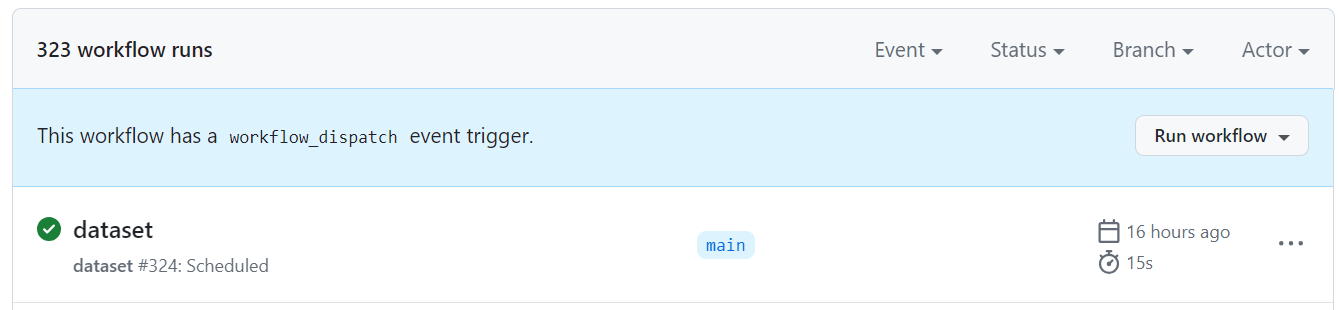

## Document your work

export("GettingStarted.mlx", "README.md")

ans = '/MATLAB Drive/scheduled-task/README.md'